# Pi Cam

This is a simple color object tracking USB camera tutoria for your robts.

Available USB webcam functions:

- webcamlist - List of webcams connected to your system

- webcam - Connection to a webcam

- preview - Preview live video dta from webcam

- snapshot - Acquire single image frame from a webcam

- closePreview - Close webcam preview window

Simrun Mutha and Jackie Zeng

clc % clear command window
clear % clear MATLAB workspace
imaqreset % clear all iamge objects

**Set up robot control system **

% Connect to raspi
    robotPi = raspi('192.168.16.71', 'pi', 'raspberry');
% Create connection to the V2 Pi Camera
    robotCam = cameraboard(robotPi, 'Resolution', '1280x720');
    
% Fix auto exposure problem set it to manual, set exposure to work in lab
% lighting. Set whitebalance to manual too. Auto exposure and white balance
% drive computer vision algorithm crazy
    SETUPPICAMERA(robotCam);


% Acquire a frame
img = snapshot(robotCam);

% Display the frame in the imaqtool window
imtool(img);

%explore image with tool
%gCamTest = input('experiment with tool, type G, then hit ENTER ','s');

clc;

%create a free floating figure for images
picamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
% figure(picamWindow) % got to camWindow for imshow
% imshow(img,'Border','tight')
% Save file
% filename = input('Input color of object:','s');
% saveas(gcf, filename)

**Run Robot Control Loop **

controlFlag = 1;
nTests = 1
r = rateControl(0.1);
reset(r);

while (controlFlag < nTests +1)
    
    %SENSE finds centroid and area of target
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    [centroids, targetArea, cleanImage] = SENSE(robotCam)
    THINK();
    ACT();
        
    %pause to allow you to move objects
    camtest = input('move objects to new position, type G, then hit ENTER', 's');
    clc;
    
    waitfor(r);                         % wait for loop cycle to complete
    controlFlag = controlFlag +1;       % increment loop
end

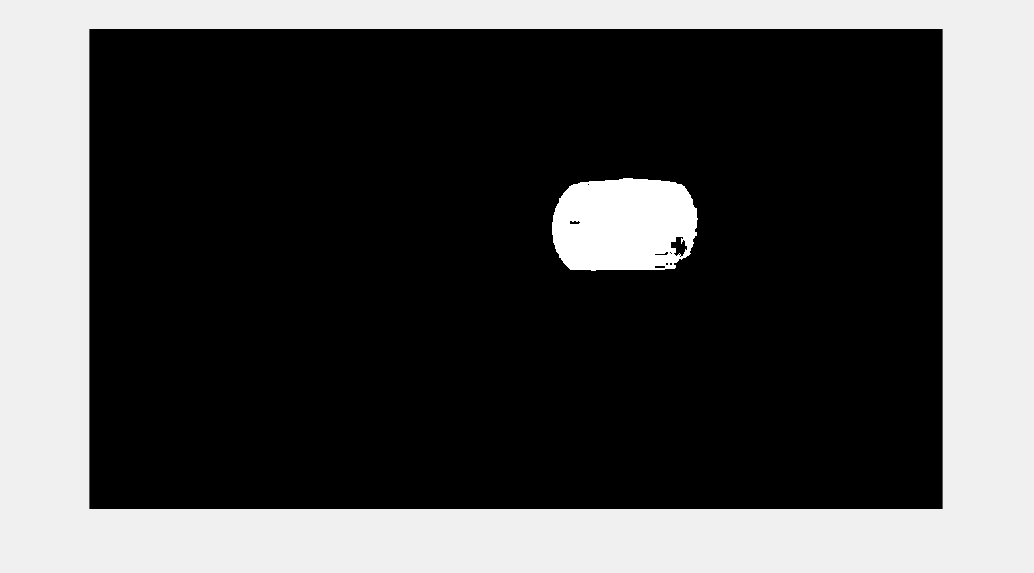

area = 26005

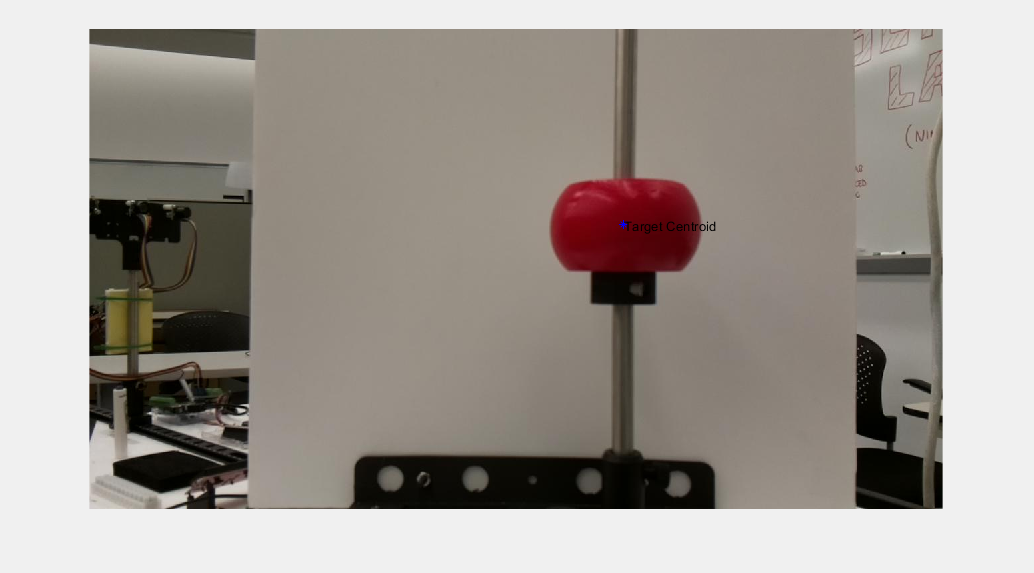

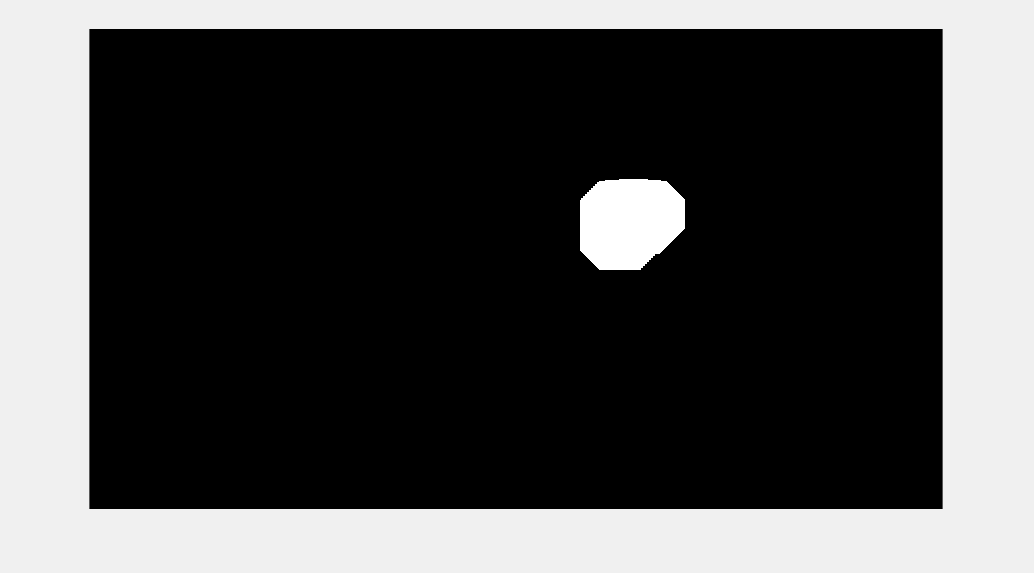

stats = struct with fields:
    BoundingBox: [694.5000 224.5000 219 139]


ans = 694.5000

hole_center_x = 347.2500

sz =          720        1280


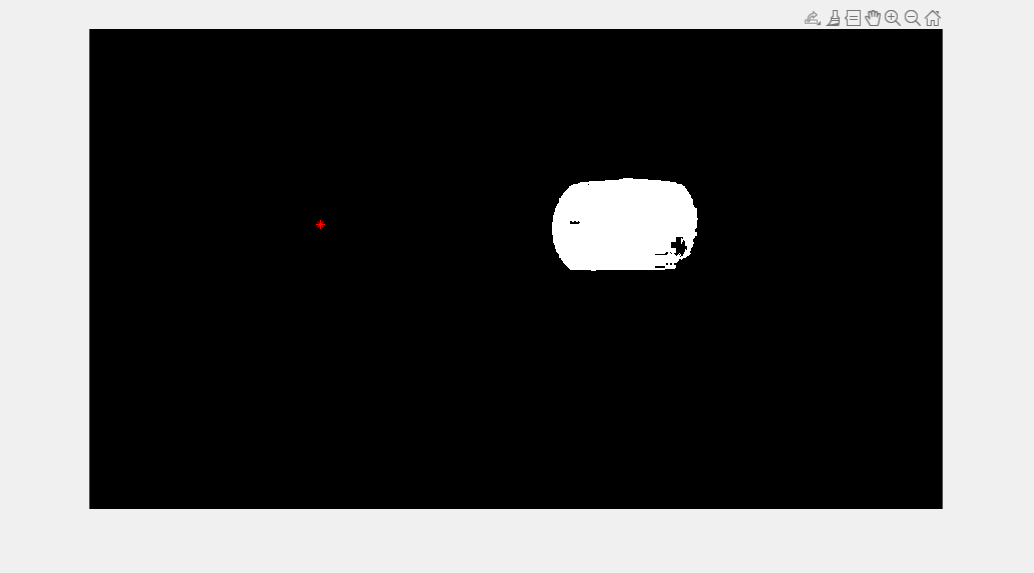

distance_cm = 12.5044

degree = 16.6459

sz = 1;
actual_distance = ones(1,sz);
area_arr = ones(1,sz);
for i = 1:sz
    
%     SETUPPICAMERA(robotCam);
    
    [centroids, targetArea, cleanImage] = SENSE(robotCam);    
%     actual_distance(1,i) = input('input distance to object (cm)');
    camtest = input('move objects to new position, type G, then hit ENTER', 's');
    clc;
    imaqreset;
    area_arr(1,i) = targetArea.Area;
    
    stats = regionprops(cleanImage,'BoundingBox')
    stats.BoundingBox(1)
    
    % FIND HOLE AND PLOT IT
    hole_center_x = FIND_HOLE(cleanImage)
    
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    figure(camWindow) % go to camWindow for imshow
    imshow(cleanImage)
    hold on
    sz = size(cleanImage)

    plot(hole_center_x,centroids(2),'r*')
    hold off
    
    % FIND BEARING
    degree = FIND_BEARINGS(targetArea.Area,centroids,hole_center_x)
end



area_arr

area_arr = 26005

actual_distance

actual_distance = 1

Calibrating Area

y = [28,32,36,40,44]
x = [58892,45758, 35327, 27468, 22621]
plot(x,y)
[m] = polyfit(x, y, 1)
x = linspace(22621,58892, 5)
dist = m(1).*x+m(2)
plot(x, dist)
% equation of line is -0.004 x + 52.2248

Testing distance calibration

[m, b] = CALIBRATE_DISTANCE(robotCam)

**Clean Shut Down**

% Stop program and clean up connection to WebCam when no longer needed

    clc
    clear robotCam
    disp('SimpleUSBCameraTutorial Done');
    
    beep

**Sense Functions**

function [] =  SETUPPICAMERA(robotCam)    
    % Fix expose to set it to respond quickly, set whitebalance to off
    robotCam.ExposureMode = 'night';
    robotCam.AWBMode = 'fluorescent';
end

function [centroids, targetArea, cleanImage] = SENSE(robotCam)
    % This function acquires a single image from the USBCamera testCam and
    % finds and returns centroids of purple area in image
    
    imaqreset;
    % capture image
    robotImage = snapshot(robotCam);
    
    % use color threshold app to create a colormask funciton ( purplemaks)
    % functions will have different anems depending on color of traget
    [targetMask, Img] = redMask(robotImage);
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    figure(camWindow)
    imshow(targetMask)
%     camtest = input('check out masked image,type G, hit Enter','s');
    clc;
    
    % Preprocess image to remove noise
    se = strel('disk',50);
    cleanImage = imopen(targetMask, se); %structure element erosion function
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    figure(camWindow)
    imshow(cleanImage)
%     camtest = input('check out cleaned image, type G, then hit enter',"s")
    clc;
    
    cleanImage = targetMask;
    %calculate the centroid of the white part of masked area(target)
    targetCenter = regionprops(cleanImage,'centroid');
    %store the x and y coordinates in a two column matrix
    centroids = cat(1,targetCenter.Centroid);
    % Display the original image with the centroid locations superimposed
    camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
    figure(camWindow) % go to camWindow for imshow
    imshow(robotImage)
    hold on
    plot(centroids(:,1),centroids(:,2),'b*')
    text(centroids(:,1),centroids(:,2), 'Target Centroid')
    hold off
%     camtest = input('check out target center, type G, and hit enter','s');
    clc;
    
    % Calculate the area of the target
    targetArea = regionprops(cleanImage,'area');
    area = targetArea.Area
    % Store the x and y coordinates in a two column matrix
    centroids = cat(1,targetCenter.Centroid);
    % Display the binary image with the centroid locations superimposed
%     camWindow = figure('name','Robot USB Camera','NumberTitle','off','Visible','on');
%     figure(camWindow) % go to camWindow for imshow
%     imshow(robotImage)
    hold on
%     plot(centroids(:,1),centroids(:,2),'b*')
    %plot(centroids(:,1),(centroids(:,2) + 10),num2str(area));
    hold off
%     camtest = input('check out target center, type G, and hit enter','s');
    clc
end

function THINK()
    % null
end

function ACT()
    % null
end

function [m, b] = CALIBRATE_DISTANCE(robotCam)
    for i = 1:2
        SETUPPICAMERA(robotCam);
    
        [centroids, targetArea, cleanImage] = SENSE(robotCam);
        
        pixel_area(i) = targetArea.Area;
        actual_distance(i) = input('input distance to object (cm)');
     
        camtest = input('Move camera, type G, then hit enter',"s");
        clc;
    end
    
   plot(pixel_area, actual_distance)
   xlabel("pixel area")
   ylabel('actual distance')
   title('distance calibration')
   
   [m,b] = polyfit(pixel_area, actual_distance, 1);
   
end


function [dist] = AREA_TO_DISTANCE(pixel_area)
      m =  -0.0004;
      b = 52.2248;
    
    dist = m*pixel_area + b;
end


function [hole_center_x] = FIND_HOLE(cleanImage)

    %calculate the boundingbox
    stats = regionprops(cleanImage,'BoundingBox');
    x = stats.BoundingBox(1);
    h_len = stats.BoundingBox(3);
    x_left = x;
    x_right = x+h_len;
    
    [image_x, image_y] = size(cleanImage);
    
    left_hole = x_left;
    right_hole = image_x - x_right;
    
    
    if left_hole > right_hole
        hole_center_x = left_hole/2;
    else
        hole_center_x = (image_x - right_hole)/2 + right_hole;
    end
end


function [degree] = FIND_BEARINGS(target_area,centroid,hole_center_x)
% finding distance to target

    target_distance = AREA_TO_DISTANCE(target_area);
    % distance between center of hole and center of target
    distance_pixels = 1280/2 - hole_center_x;
    %35 is distance in cm and 819 is pixel distance.
    distance_cm = distance_pixels*35/819.41
    % find bearing
    degree = atand(distance_cm/target_distance);
end